# GReS - Poroelasticity (Terzaghi's problem)

## Introduction

In this tutorial, we will build a fully coupled Poroelasticity model implementing the Terzaghi problem. Terzaghi problem is a standard benchmark for Poroelasticity, which couple a Single phase flow model with a mechanical model. 

cd(fullfile(gres_root,'Tutorial','terzaghiPoroelasticity'))
terzaghi_root = fullfile(gres_root,'Tests','Terzaghi_Biot');

## Governing equations

$$div(\mathbf{\bar{\sigma'}}) - \alpha \nabla p = -\mathbf{F}$$                    Balance of linear momentum in Porous media

$$    div\bigg( \frac{\mathbf{\bar K}}{\mu} \nabla p \bigg) - \alpha \frac{\partial \epsilon}{\partial t} - \phi \beta \frac{\partial p}{\partial t} = q$$  Mass conservation of slightly compressible fully saturated fluid

Where:

 $$\mathbf{\bar{\sigma'}}$$ is the effective stress;

$p$ is the pore pressure;

$\mathbf{F}$ represents body forces (such as gravity);

$\alpha$ is the Biot coefficient;

$\phi \;$ is the porosity

$\beta \;$is the fluid compressibility

$\mathbf{\bar K}$  is the intrinsic permeability tensor;

$\mu$ is the dynamic viscosity;

$q$  is an external source term.

The following boundary conditions can be prescribed


$$  $$
\begin{cases}
    \mathbf{u}(\mathbf{x},t) = \mathbf{u}_D(\mathbf{x},t) 
    & \text{on } \, \Gamma_D:\ \text{prescribed displacements} \\[6pt]

    \bar{\mathbf{\sigma}}(\mathbf{x},t) \cdot \mathbf{n}(\mathbf{x}) = \mathbf{t}_N(\mathbf{x},t) 
    & \text{on }  \,\Gamma_N:\ \text{surface forces} \\[6pt]

    p(\mathbf{x},t) = p_D(\mathbf{x},t) 
    & \text{on } \,  \Gamma_p:\ \text{prescribed pressure} \\[6pt]

    \mathbf{q}(\mathbf{x},t) \cdot \mathbf{n}(\mathbf{x}) = q_N(\mathbf{x},t) 
    & \text{on } \, \Gamma_q:\ \text{prescribed flux}
\end{cases}
$$
$$


The primary variable of the problem are the solid displacements and the fluid pressures.

For the details on the above equations see Castelletto,2015.

## Problem setting

We simulate the consolidation of a poroelastic fluid-saturated column of height $H$ having unit cross-section. The column is instantaneously loaded at time  = 0 s with a constant compressive traction  $p_T$ applied on the top face as shown in the figure below. Only the loaded face is permeable to fluid flow, with the remaining parts of the boundary subject to roller constraints and impervious.

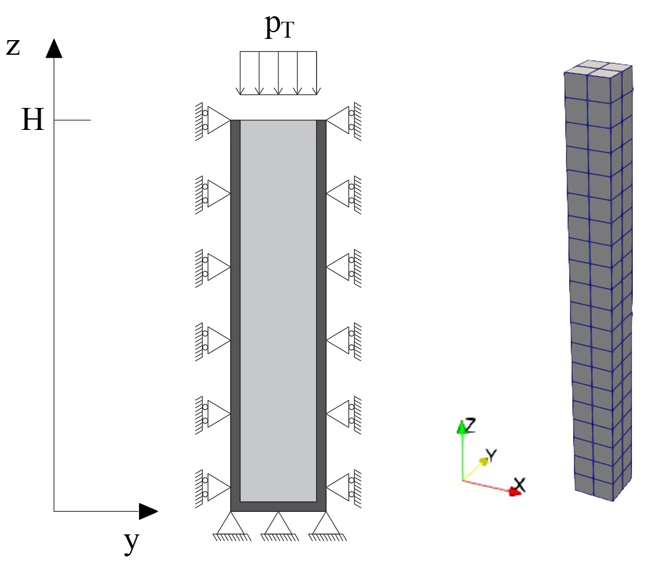

The analytical solutions can be found in Castelletto,2015

## Model setup

 The first step is the definition of the parameters of the simulation creating an object of the class` SimulationParameters, `which requires a .xml file as input. 

simParam = SimulationParameters(fullfile(terzaghi_root,"Input",'simparam.xml'));

simParam

simParam =   SimulationParameters with properties:

                         itMaxNR: 10
                     itMaxConfig: 10
                          relTol: 1.0000e-08
                          absTol: 1.0000e-09
                           pNorm: 2
                           theta: 1
                           dtIni: 0.5000
                           dtMin: 0.5000
                           dtMax: 5
                            tIni: 0
                            tMax: 180
                         multFac: 1.1000
                          divFac: 2
                         pTarget: []
                         sTarget: 0.4000
                        NLSolver: 'Newton'
                    goOnBackstep: 0
                 isTimeDependent: 1
    attemptSimplestConfiguration: 0


We then import the mesh from a `.msh` file, as expained in the [previous tutorial](matlab:open('..\01_meshInput\meshIO.mlx')).

topology = Mesh();
fileName = fullfile(terzaghi_root,"Input",'Mesh','Column_hexa.msh');
topology.importMesh(fileName);

To initialize the Finite Elements kernels in our model, we need to create an instance of the `Elements` class. We need to specify the order of integration, that is the number of Gauss points in each direction. Since the mesh consists of 8 nodes Hexahedra, we need 2 GP for exact integration.

gaussOrder = 2;
elems = Elements(topology,gaussOrder)

elems =   Elements with properties:

             mesh: [1×1 Mesh]
      mapVTK2elem: [29×1 double]
            elems: {[]  [1×1 Quadrilateral]  []  []  [1×1 Hexahedron]  []  []  []}
     nCellsByType: [0 3200 0 0 0]
      nSurfByType: [0 3232 0]
    vtk3DTypeList: [10 12 13 14 29]
    vtk2DTypeList: [5 9 28]
       nNodesElem: [3 4 9 4 8 27]


To define the Materials

mat = Materials(fullfile(terzaghi_root,"Input",'materials.xml'));

we need to input a xml file containing two blocks, one for solids and one for fluids

In the <Solid cellTags = "XXX"> we specify all the properties associated with the rock: the `<Constitutive>` block holds the parameters of the specific constitutive model,  while the` <PorousRock> `block contains the porosity, the rock compressibility, the specific weight and the intrinsic permeabillity. Here, the grid has only one cellTag, to which we assign the material.

This fluid block `holds `the specific weight of the fluid (here assumed to be 0), the fluid compressibility, and the dynamic viscosity`.`

**The user is responsible for the dimensional consistency of all physical quantities involved in the model.**

We then create an instance of the `Faces `class.

faces = Faces(topology)

faces =   Faces with properties:

       nodes2Faces: [44864×1 double]
            mapN2F: [11217×1 double]
    faces2Elements: [19200×2 double]
            mapF2E: [3201×1 double]
     faceNeighbors: [11216×2 double]
      faceCentroid: [11216×3 double]
        faceNormal: [11216×3 double]
            nFaces: 11216


For following object definitions, we need to wrap the instances of `Mesh(), Elements() `and `Faces()` into a structure named `grid.`

grid = struct('topology',topology,'cells',elems,'faces',faces);

We proceed defining the details of the output of the current simulation, creating an instance of the `OutState `class.

printUtils = OutState(topology,fullfile(terzaghi_root,"Input",'output.xml'));

We then proceed defining the boundary conditions.

% Creating boundaries conditions.
bound = Boundaries(fullfile(terzaghi_root,"Input","boundaries.xml"),grid);

Let us take a look at the boundary condition file:

We use the surfaceTag defined in the Mesh object to assign the Boundary conditions.

## Solution processing

### Discretizer class

Up to now we only define the input for our simulation. It is time to run our model.

First, we instanciate the `Discretizer `class creating an object called `domain.`

% Create object handling construction of Jacobian and rhs of the model
domain = Discretizer('Boundaries',bound,...
                     'OutState',printUtils,...
                     'Materials',mat,...
                     'Grid',grid);

This class wraps all the objects previously defined, and in the `solver `property stores a database with the physical solvers of the model. Another important property is `State`, which is an object storing primary variables and derived quantities of the model for a specific time instant. 

domain.state

ans =   State with properties:

       t: 0
    data: []


domain.state.data


ans =

     []



The state object does not store any varriable, since we not yet defined a PhysicsSolver. We add [BiotFullySaturated](matlab:open('..\..\Code\discretizer\PhysicsSolvers\Coupling\BiotFullySaturated.m')) solver implementing the fully coupled set of governing equations. 

domain.addPhysicsSolver('solver_TPFA.xml');

The solver xml input file reads

We can specify the SinglePhysics solvers being coupled with their target regions. Note that the flow solver implements TPFA Finite Volumes. 

We can inspect the newly added physics solver 

biot = domain.getPhysicsSolver('BiotFullySaturated')

biot =   BiotFullySaturated with properties:

            Q: []
       domain: [1×1 Discretizer]
         dofm: [1×1 DoFManager]
         mesh: [1×1 Mesh]
     elements: [1×1 Elements]
        faces: [1×1 Faces]
          bcs: [1×1 Boundaries]
    materials: [1×1 Materials]
    simparams: []


Property `Q `stores the coupling block, free from boundary conditions. We can also inspect the discretization scheme used for the flow model

biot.getFlowScheme()

ans = "FVTPFA"

Before running the simulation, we are still missing the initial conditions! 

Initial conditions are applied "manually" by directly modifying the `state `object before the simulation takes place. This means that **no input files are needed to apply the initial conditions.**

F = -10; % vertical force
applyTerzaghiIC(domain.state,mat,topology,F);

### Simulation loop

We are all set to run our first simulation! Single domains fully coupled simulations are implemented with the GeneralSolver`(); `

Solver = GeneralSolver(simParam,domain)

Solver =   GeneralSolver with properties:

     simparams: [1×1 SimulationParameters]
       domains: [1×1 Discretizer]
    interfaces: []
     linsolver: [1×1 linearSolver]


The actual simulation (i.e the time loop) is performed by the `NonLinearLoop(). `We set the verbosity of GReS to monitor the solution

gresLog().setVerbosity(2)
Solver.NonLinearLoop();


TSTEP 1   ---  TIME 0.500000  --- DT = 5.000000e-01
-----------------------------------------------------------

Configuration iteration n. 0 
Iter     ||rhs||     ||rhs||/||rhs_0||
0     9.805844e-05     1.000000e+00
1     8.968015e-15     9.145582e-11

TSTEP 2   ---  TIME 1.050000  --- DT = 5.500000e-01
-----------------------------------------------------------

Configuration iteration n. 0 
Iter     ||rhs||     ||rhs||/||rhs_0||
0     3.219037e-06     1.000000e+00
1     1.034348e-14     3.213223e-09

TSTEP 3   ---  TIME 1.655000  --- DT = 6.050000e-01
-----------------------------------------------------------

Configuration iteration n. 0 
Iter     ||rhs||     ||rhs||/||rhs_0||
0     1.109307e-06     1.000000e+00
1     1.152054e-14     1.038535e-08

TSTEP 4   ---  TIME 2.320500  --- DT = 6.655000e-01
-----------------------------------------------------------

Configuration iteration n. 0 
Iter     ||rhs||     ||rhs||/||rhs_0||
0     7.061312e-07     1.000000e+00
1     1.196665e-

simParam.dtIni

ans = 0.5000

is progressively incremented due to the multiplicative factor

simParam.multFac

ans = 1.1000

and stops at

simParam.tMax

ans = 180

## Post processing

We can finalize our simulation and write the output.

domain.outstate.finalize();

We can open the generated .pvd file in the `Outputs` using [Paraview](https://www.paraview.org/). 

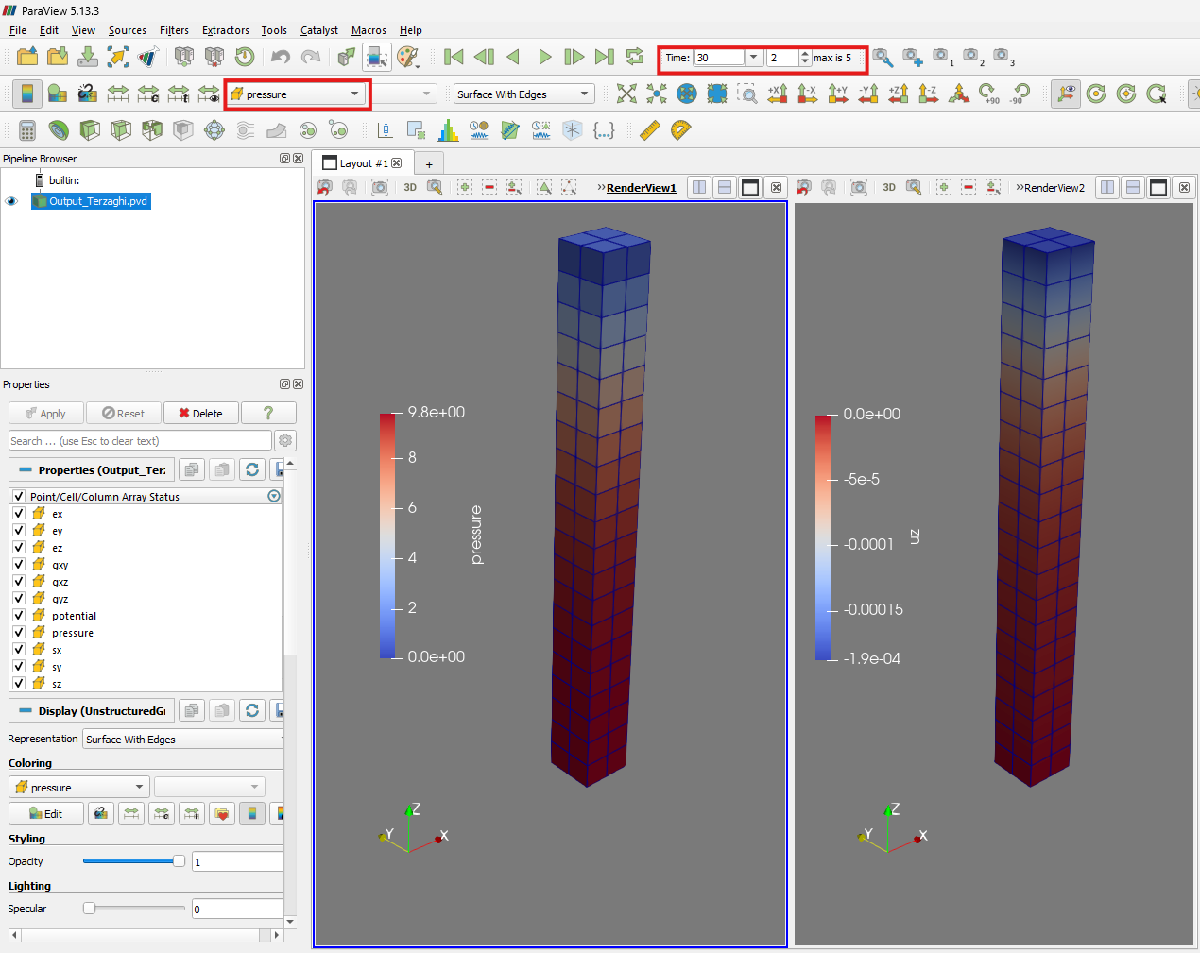

## References

*Nicola Castelletto, Joshua A White, and HA Tchelepi. Accuracy and convergence properties of the fixed-stress iterative solution of two-way coupled poromechanics. International Journal for Numerical and Analytical Methods in Geomechanics,39(14):1593–1618, 2015.*